# Assignment 3: Stokes flow around a cylinder

## Introduction

Consider the following strong form of a steady Stokes flow around a cylinder with R=0.08 and inside a channel with moving walls:

  
$$\begin{cases}-\nabla\cdot(\nu\nabla v-pI_{nsd})=s & \textrm{in} \ \Omega \\
\nabla\cdot v = 0 & \textrm{in} \ \Omega  \\
v=v_{in} & \textrm{on} \ \Gamma_{left} \\
v=v_{w} & \textrm{on} \ \Gamma_{top}\cup\Gamma_{bot} \\
n\cdot\sigma=t & \textrm{on} \ \Gamma_{right}&
\end{cases}$$


where $\Omega$ consists of a 1x1 square domain with a circle inclusion, centered at the middle. We will consider homogeneous Neumann boundary conditions at the outlet ($\Gamma_{right}$), i.e $t=0$. Besides, we will neglect the body forces, i.e $s=0$. Non-slip conditions are considered for all physical boundaries. We can solve this problem through finite elements by calling the class 'StokesFlowCylinder'. However, we need to define some preliminar properties.

## Mesh set-up

We first define the 2D background mesh to discretize the square domain, which will be composed of quadrilateral elements. With the following lines we can define, for instance, a mesh consisting of 100x100 elements:

clear;
close all;

L = 1;
H = 1;
m = QuadMesh(L,H,100,100);

It is worth mentioning that the circle inclusion is performed inside the class 'StokesFlowCylinder', and there is no need to do it by ourselves!

## Defining the boundary conditions and time step

Lastly, we show below the boundary conditions and the time step employed, which are the only user-defined parameters:

vInlet = [1,0];
vWalls = [1,0];
dtime  = Inf;

We start by setting the moving walls velocity equal to the inlet velocity. Since we want to solve a steady problem, we can set the time step equal to infinite.

## Defining the physical problem

With all the preliminaries completed, we create the physical problem, including the cylinder dimensions that will be cut from the background mesh, as depicted below:

s.backgroundMesh = m;
s.center         = [0.5,0.5];
s.radius         = 0.08;
s.velocityOrder  = 'P2';
s.pressureOrder  = 'P1';
physicalProblem  = StokesFlowCylinder(s);

## Questions

**1. Note that we start the problem by setting the moving walls velocity equal to the inlet velocity. Which is the main reason of this strategy?**

This helps simulate the free flow of the velocity along the cylinder as if it were in an open space and not contained within a channel.

**2. We can obtain the velocity and pressure distribution by running this line:**

[v,p] = physicalProblem.solve(vInlet,vWalls,dtime);

However, there is a bug inside the code and it will not work now. Solve the bug and obtain and plot the velocity and pressure distributions as follows:

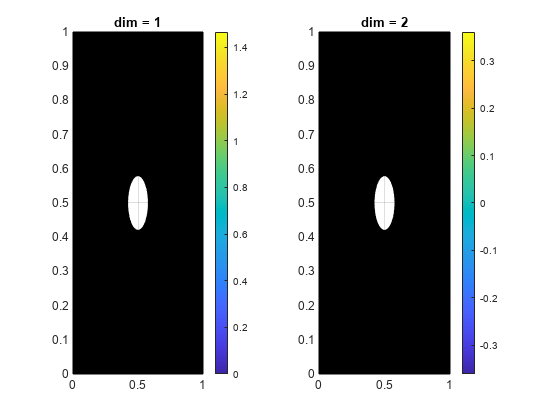

v.plot();

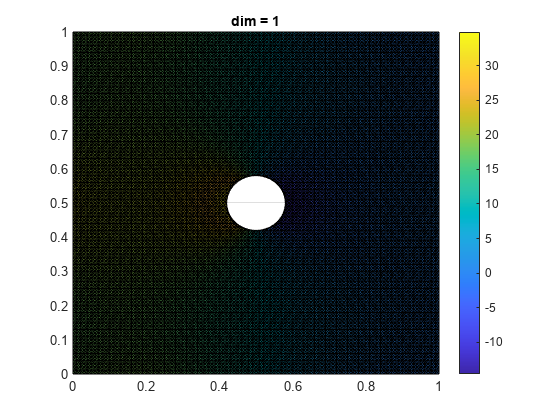

p.plot();

**3. With the pressure distribution computed, we can obtain its field also at the cylinder wall, along with the corresponding 1D mesh, by running:**

[pCyl,bMesh] = physicalProblem.obtainPressureDistributionAtCylinder(p);

**Given the pressure distribution at the cylinder wall, we would like to compute the lift and drag forces as follows:**

normalVectors = computeNormalVectors(bMesh);
nx            = LagrangianFunction.create(bMesh,1,'P0');
ny            = LagrangianFunction.create(bMesh,1,'P0');
nx.fValues    = normalVectors(:,1);
ny.fValues    = normalVectors(:,2);
ss.operation  = @(x) -pCyl.evaluate(x).*nx.evaluate(x);
pNx           = DomainFunction(ss);
D             = Integrator.compute(pNx,bMesh,'QUADRATIC');
ss.operation  = @(x) -pCyl.evaluate(x).*ny.evaluate(x);
pNy           = DomainFunction(ss);
L             = Integrator.compute(pNy,bMesh,'QUADRATIC');

**However, the computeNormalVectors function (see 'Auxiliar functions definition' section) is incompleted. Complete the function and compute the lift and drag forces at this conditions.**

[L_3,D_3] = computeLiftAndDrag(pCyl,bMesh);

**4. Using a new auxiliar function based in the lines of previous question, plot the evolution of lift and drag coefficients in function of different values of the moving walls velocity.**

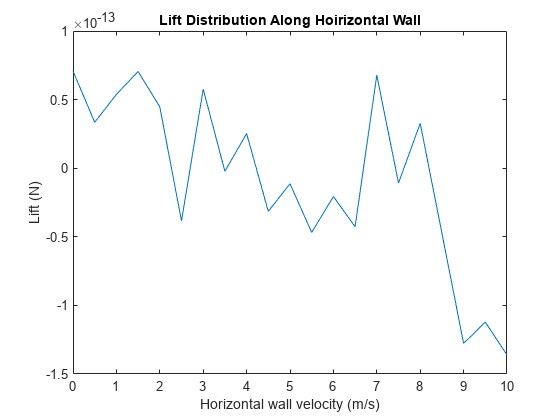

% Solving the problem
wallVel = 0:0.5:10;
L_4 = zeros(size(wallVel));
D_4 = zeros(size(wallVel));
for i = 1:numel(wallVel)
    vWalls = [wallVel(i),0];
    [v,p] = physicalProblem.solve(vInlet,vWalls,dtime);
    [pCyl,bMesh] = physicalProblem.obtainPressureDistributionAtCylinder(p);
    [L_4(i),D_4(i)] = computeLiftAndDrag(pCyl,bMesh);
end

% Plots
figure()
plot(wallVel,L_4)
title('Lift Distribution Along Horizontal Wall')
xlabel('Wall velocity (m/s)')
ylabel('Lift (N)')

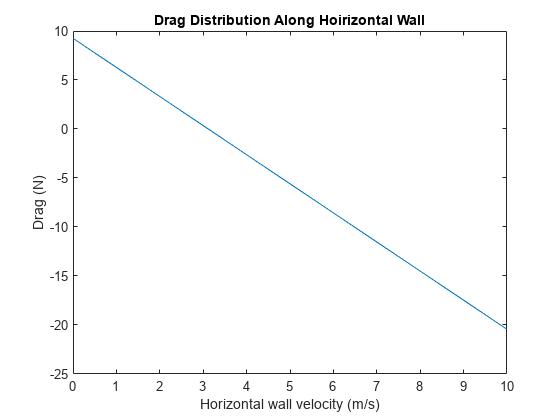


figure()
plot(wallVel,D_4)
title('Drag Distribution Along Horizontal Wall')
xlabel('Wall Velocity (m/s)')
ylabel('Drag (N)')

**5. Define a new physical problem using P1 finite element order for both the velocity and pressure. Use the initial moving wall velocity and plot the velocity and pressure distributions. What can you observe and why?**

s.velocityOrder  = 'P1';
s.pressureOrder  = 'P1';
physicalProblem  = StokesFlowCylinder(s);
vWalls           = [1,0];
[v,p] = physicalProblem.solve(vInlet,vWalls,dtime);

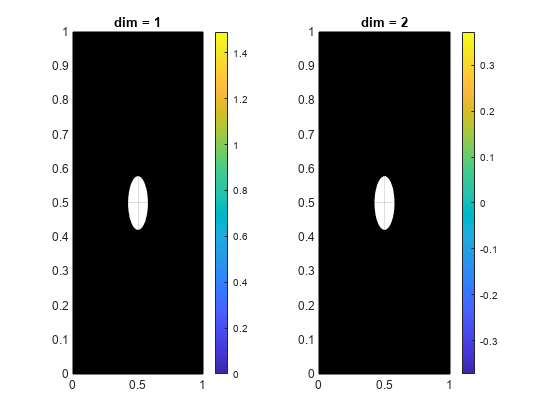

v.plot()

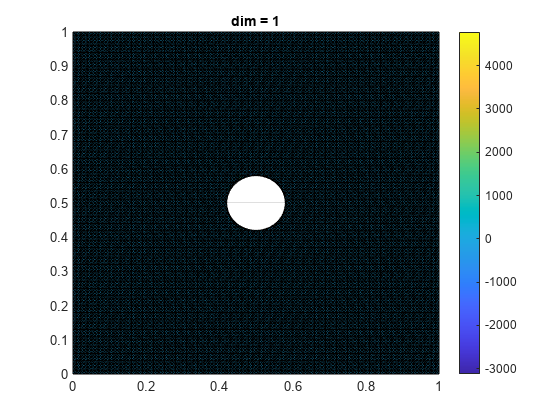

p.plot()

When setting up the physical problem using P1 finite elements, the output is a singular matrix due to insufficient degrees of freedom relative to the constraints. Despite this, the velocity distribution obtained appears physically correct, indicating that P1 elements can capture essential velocity features even under these conditions. The pressure distribution exhibits significant oscillations, indicating numerical instability. This instability arises because P1 elements are not suitable for pressure approximation in incompressible flow, violating the inf-sup condition necessary for stability.

## **Auxiliar functions definition**

function normalVectors = computeNormalVectors(bMesh)
    % Initialize normalVectors with zeros
    numElements = size(bMesh.coordElem, 3);
    normalVectors = zeros(numElements, 2);
    
    % Loop over each element
    for iElem = 1:numElements
        nodesElem = squeeze(bMesh.coordElem(:, :, iElem)); % Nodes for current element
        dx = nodesElem(1, 2) - nodesElem(1, 1);
        dy = nodesElem(2, 2) - nodesElem(2, 1);
        vect = [dx; dy];
        vectMagnitude = sqrt(vect(1)^2 + vect(2)^2);
        
        % Normalize the vector
        if vectMagnitude == 0
            normalizedVect = [0; 0];
        else
            normalizedVect = vect / vectMagnitude;
        end
        
        rotationMatrix = [0 -1; 1 0];
        normalVec = rotationMatrix * normalizedVect; %normal ve4ctor computation

        normalVectors(iElem, :) = normalVec';
    end
end


function [L,D] = computeLiftAndDrag(pCyl,bMesh)
    normalVectors = computeNormalVectors(bMesh);
    nx            = LagrangianFunction.create(bMesh,1,'P0');
    ny            = LagrangianFunction.create(bMesh,1,'P0');
    nx.fValues    = normalVectors(:,1);
    ny.fValues    = normalVectors(:,2);
    ss.operation  = @(x) -pCyl.evaluate(x).*nx.evaluate(x);
    pNx           = DomainFunction(ss);
    D             = Integrator.compute(pNx,bMesh,'QUADRATIC');
    ss.operation  = @(x) -pCyl.evaluate(x).*ny.evaluate(x);
    pNy           = DomainFunction(ss);
    L             = Integrator.compute(pNy,bMesh,'QUADRATIC');
end

